clear
load jogging.mat
Acceleration.time=timeElapsed(Acceleration.Timestamp);
Acc=Acceleration{:,["time", "X" ,"Y" ,"Z"]};
Acc=Acc(Acc(:,1)>10 & Acc(:,1)<20,:);

Acc =    10.0100   -2.5406  -21.9544   -1.8888
   10.1070    3.6724   -8.2499    2.6234
   10.2040   -2.5807   -1.5996   -1.1958
   10.3010    4.9687  -13.3328    1.9331
   10.3980   -3.8527  -16.2562    3.6553
   10.4950   -0.1594  -10.6576   -7.1462
   10.5920   -5.2173   -0.4519   -2.7203
   10.6890    1.6992  -22.1522    0.4128
   10.7860   -4.0519  -14.1559   -0.8569
   10.8830    6.9287    0.9975    3.4265


Acc_ =    10.0100   22.1815
   10.1070    9.4037
   10.2040    3.2632
   10.3010   14.3593
   10.3980   17.1018
   10.4950   12.8327
   10.5920    5.9012
   10.6890   22.2211
   10.7860   14.7493
   10.8830    7.7938


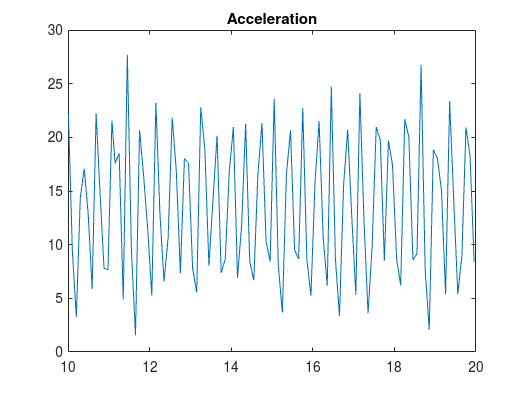

Acc_=[Acc(:,1),sqrt((Acc(:,2)).^2+(Acc(:,3)).^2+(Acc(:,4)).^2)];


[rows,~]=size(Acc_);
high_points=[0 0];
bottom_points=[0 100];
avg_value=mean(Acc_(:,2))

avg_value = 13.5318

flag=1;
top=[0 0];
bottom=[0 100];
for i=1:rows
    if flag==1
        if Acc_(i,2) >avg_value
            if Acc_(i,2)>top(2)
                top=Acc_(i,:);
            end
        else
            high_points=[high_points; top];
            flag=0;
            top=[0 0];
            if Acc_(i,2)<bottom(2)
                bottom=Acc_(i,:);
            end
        end
    else
        if Acc_(i,2)<=avg_value
            if Acc_(i,2)<bottom(2)
                bottom=Acc_(i,:);
            end
        else
            bottom_points=[bottom_points;bottom];
            flag=1;
            bottom=[0 100];
            if Acc_(i,2)>top(2)
                top=Acc_(i,:);
            end
        end
    end
end
high_points=high_points(2:end,:);

high_points =    10.0100   22.1815
   10.3980   17.1018
   10.6890   22.2211
   11.0770   21.5650
   11.4540   27.6899
   11.7540   20.6551
   12.1540   23.2285
   12.5540   21.8405
   12.8540   18.0302
   13.2540   22.7886


[rows_top,~]=size(high_points);

rows_top = 28

bottom_points=bottom_points(2:end,:);

bottom_points =    10.2040    3.2632
   10.5920    5.9012
   10.9800    7.6674
   11.3540    4.8962
   11.6540    1.5631
   12.0540    5.2346
   12.3540    6.5650
   12.7540    7.3419
   13.1540    5.5382
   13.4540    8.0383


[rows_bot,~]=size(bottom_points);

rows_bot = 27

duration=[];


duration =

     []



step_height=[];


step_height =

     []



for i=2:rows_top-1
    dur=(-high_points(i-1,1)+high_points(i+1,1))/2;
    height=(high_points(i,2)-bottom_points(i-1,2)+high_points(i,2)-bottom_points(i,2))/2;
    duration=[duration,dur];
    step_height=[step_height, height];
end
duration=duration';

duration =     0.3395
    0.3395
    0.3825
    0.3385
    0.3500
    0.4000
    0.3500
    0.3500
    0.4000
    0.4000


step_height=step_height';

step_height =    12.5196
   15.4368
   15.2833
   24.4603
   17.2562
   17.3287
   14.8870
   11.5901
   16.0004
   12.4484


result2=[duration, step_height]

result =     0.3395   12.5196
    0.3395   15.4368
    0.3825   15.2833
    0.3385   24.4603
    0.3500   17.2562
    0.4000   17.3287
    0.3500   14.8870
    0.3500   11.5901
    0.4000   16.0004
    0.4000   12.4484
